**Simulación del volumen en función de la temperatura y la presión para la ecuación de los gases ideales utilizando caminos aleatorios.**

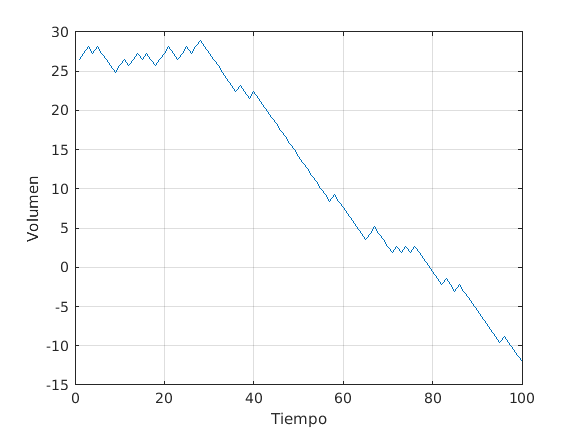

%Función para gases ideales
Tp(1)=323; %Temperatura en grados Kelvin siendo el punto medio y siendo el 373 el máximo 
V(1)=26.5; %Volumen inical en Litros
n=1; %#moles
R=0.082; %constante de los gases ideales
P=1; %1atm de presión
t=100; %tiempo del proceso en segundos
dT=10;%Delta de temperatura
for i=2:t%loop de conteos
    T=(rand*100)+273; %conversión de la temperatura de grados centigrados a grados Kelvin
    if (T > Tp) %se comparan ambas temperaturas dentro de la escala Kelvin
        Tp(i)=Tp(i-1)+dT; %Tal y como se hace en anteriores ejercicios si la probabilidad es mayor a la temperatura promedio se tiene +1
        V(i)=n*R*Tp(i)/P; %Se hace la respectiva formula para calcular el volumen que tiene el gas dentro del tiempo determinado
    else
        Tp(i)=Tp(i-1)-dT; %si la probabilidad es menor a la temperatura promedio se tiene -1
        V(i)=n*R*Tp(i)/P; %Se hace la respectiva formula para calcular el volumen que tiene el gas dentro del tiempo determinado, por eso es v(i)
    end

end
plot(1:t,V)
grid on
xlabel('Tiempo');
ylabel('Volumen');

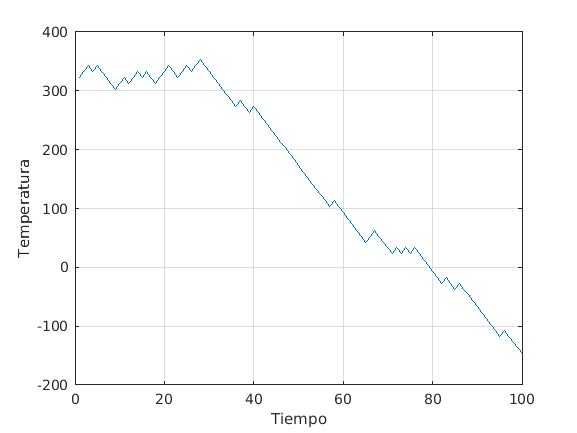


plot(1:t,Tp)
grid on
xlabel('Tiempo');
ylabel('Temperatura');

### **Análisis:**

El ejercicio de aplicación está enfocado en determinar la función para los gases ideales.

Para comenzar, la definición de las variables:

- -Se define la variable "Tp", que hace referencia a la temperatura en grados Kelvin. 

- Se define la variable "V" que hace referencia el volumen inical en Litros.

- Se define "n" como la unidad de medida en moles con la cual se va a trabajar el ejercicio.

- Se define "R" como la constante que tendrán los gases ideales.

- Se define "P" que hace referencia a las atmosferas de presión para el ejercicio 

- Se define "dT" como el delta de temperatura manejado en el ejercicio

- -Se devine "t", como el eje x de la gráfica, el cual representa el tiempo de ejecución, simulando que cada "step" desde el valor de partida hasta "T", equivale al paso del tiempo total de ejecución.

#### Explicación de los ciclos "for"

- -El primer bucle for será el encargado de generar la trayectoria a través de la variable "i", que para este código se ha definido desde 2 hasta "t".

- Se pasa la varible T la cual tiene un valor randomizado, de grados centigrados a grados Kelvin, esto se hace para dar concordancia al contexto del ejercicio que plantea que la temperatura se debe determinar en grados Kelvin. Cabe resaltar que si en grados centigrados se tiene un rango de 0 a 1 y el punto medio entre ambos será de 0.5. Pues para la escala de Kelvin será de 273 hasta 373, con un punto medio de 323.

**Explicación de los ciclos "if"**

- Ahora cuando comparamos la variable "T" con la variable "Tp" hacemos referencia a la comparación que se hace del valor randomizado si es mayor  que la probabilidad determinada por la escala de Kelvin la cual es 323 se cumple el primer caso en el que la variable de partida le es adicionado ese valor de "dT" el cual hace referencia al delta de la temperatura del ejercicio.

- Luego de esto se calcula el valor del volumen del ejercicio. En el caso contrario

-  Si "rand" es decir "T" genera un valor aleatorio menor a "Tp", cumpliendo el segundo caso, a la variable de partida le será sustraído el valor de "dT"

- Luego de esto se calcula el valor del volumen del ejercicio

Este bucle for se llevará a cabo hasta que se hayan completado los 100 casos estipulados para "t".

Algo importante a resaltar de esto es que si nos damos cuenta crear las gráficas para el volumen "V" y para la la variable "Tp" que es la temperatura promedio en grados Kelvin es que son directas la una con la otra siguiendo la formula $V\left(T\right)=\frac{n*R*T}{P}$ y que así mismo sea equivalente a $\uparrow V\left(T\right)=K*T\uparrow$ donde una aumenta a razón de la otra.

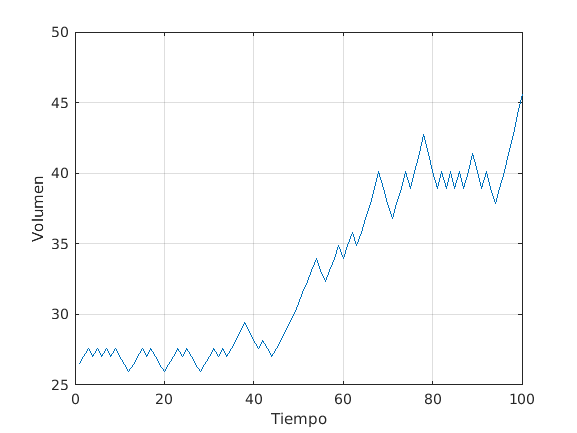

%Función para gases ideales
Pp(1)=1; %Presión promedio atm
V(1)=26.5; %Volumen inical en Litros
n=1; %#moles
R=0.082; %constante de los gases ideales
T=323; %Temperatura en Kelvin
t=100; %tiempo del proceso en segundos
dP=0.02;%Delta de presión
for i=2:t %loop de conteos
    P=rand+0.5; %Al valor randomizado se le suma 0.5 debido a que una presión en 0 no tiene concordancia con el contexto del ejercicio. Debido a esto la escala se correo de 0.5 hasta 1.5 
    if (P > Pp) %Comparación del valor randomizado de la presión con la presión promedio
        Pp(i)=Pp(i-1)+dP;%si la probabilidad de la presión es mayor a la presión promedio se tiene +1
        V(i)=(n*R*T)/Pp(i);%Se calcula el valor del volumen
    else
        Pp(i)=Pp(i-1)-dP;%si la probabilidad de la presión es menor a la presión promedio se tiene -1
        V(i)=(n*R*T)/Pp(i);%Se calcula el valor del volumen
    end
end
    
plot(1:t,V)
grid on
xlabel('Tiempo');
ylabel('Volumen');

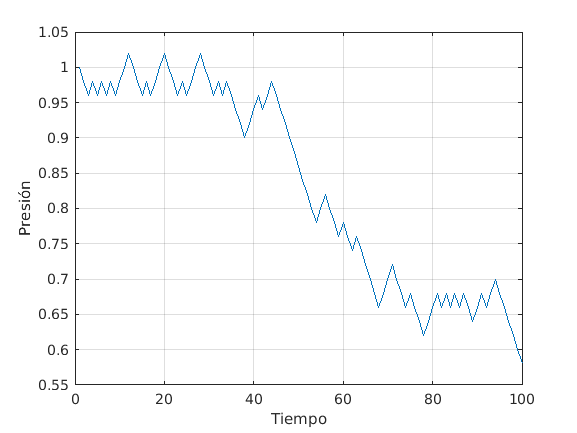


plot(1:t,Pp)
grid on
xlabel('Tiempo');
ylabel('Presión');

El ejercicio de aplicación está enfocado en determinar la función para los gases ideales.

Para comenzar, la definición de las variables:

- -Se define la variable "Pp", que hace referencia a la presión promedio en atmosferas 

- Se define la variable "V" que hace referencia el volumen inical en Litros.

- Se define "n" como la unidad de medida en moles con la cual se va a trabajar el ejercicio.

- Se define "R" como la constante que tendrán los gases ideales.

- Se define "T" que hace referencia a la temperatura en grados Kelvin 

- Se define "dP" como el delta de presión manejado en el ejercicio

- -Se devine "t", como el eje x de la gráfica, el cual representa el tiempo de ejecución, simulando que cada "step" desde el valor de partida hasta "T", equivale al paso del tiempo total de ejecución.

#### Explicación de los ciclos "for"

- -El primer bucle for será el encargado de generar la trayectoria a través de la variable "i", que para este código se ha definido desde 2 hasta "t".

- A la variable "P" cuyo valor está randomizado, se le suma 0.5 de tal manera que pueda tener concordancia con el contexto que propone el ejercicio ya que una presión de 0 atm no tendría sentido. Por eso al hacer la sumatoria en ese paso, se tiene que la escala es corrida hacía la derecha de tal manera que nuestro punto inicial sea 0.5, y nuestro punto final sea 1.5, siendo el valor 1 nuestro punto medio en esa escala.

**Explicación de los ciclos "if"**

- Ahora cuando comparamos la variable "P" con la variable "Pp" hacemos referencia a la comparación que se hace del valor randomizado si es mayor  que la probabilidad determinada se cumple el primer caso en el que la variable de partida le es adicionado ese valor de "dP" el cual hace referencia al delta de presión del ejercicio.

- Luego de esto se calcula el valor del volumen del ejercicio. En el caso contrario

-  Si "rand" es decir "P" genera un valor aleatorio menor a "Pp", cumpliendo el segundo caso, a la variable de partida le será sustraído el valor de "dP"

- Luego de esto se calcula el valor del volumen del ejercicio

Este bucle for se llevará a cabo hasta que se hayan completado los 100 casos estipulados para "t".

Algo importante a resaltar de esto es que si nos damos cuenta crear las gráficas para el volumen "V" y para la la variable "Pp" que es la presiób promedio en atmosferas es que son inversas la una con la otra siguiendo la formula $V\left(P\right)=n*R*T*\frac{1}{P}$ y que así mismo sea inverso a $\downarrow V\left(P\right)=K*\frac{1}{P}\uparrow$ donde una si es cierto que una aumenta, la otra disminuye es decir una relación inversa.